% Assignment 3 
% Author - Jake Betenson

% 2. The code Gaussfastresid.m  computes the residual of randomly chosen systems 
% of equations for increasingly larger systems of  equations. Modify the code 
% to do two steps of iterative refinement and plot the new residual on the same 
% graph as the original.  The matlab command  y = single(x) results in y being 
% a single precision version of x.  Modify you existing code further to put the 
% original solution to the equations into a single precision array.  
% Again perform two steps of iterative refinement starting with the residual 
% calculated with the single precision version of the residual to show that  
% you can reduce the size of the residuals. Plot the infinity norms of the 
% different residuals against n  to illustrate your results.
% Code stub provided as part of lecture slides, iterative refinement added
% by author.

clear all
t = zeros(1,200);
normb = zeros(1,200);
norm2step=zeros(1,200); %holds 2 steps of refinement residuals
norm2stepSP=zeros(1,200); %holds 2 steps of single precision refined residuals
normbsp=zeros(1,200); %holds 2 steps of single precision refined residuals
mormbb= normb;
normbre= normb;
model = zeros(1,200);
for m = 1:200
    %Ax = b
    n = m*10;
    A = rand(n,n);
    b = rand(n,1);
    x = A\b; %original result
    xsp = single(x); %single precision result
    r = A*x-b; %first residual
    rsp = single(A*xsp-b); %single precision residual
    
    %iterative refinement
    y = A\-r;
    ysp = single(A\-rsp);    
    x = x+y;
    xsp = single(xsp + ysp);    
    r2 = A*x-b;
    rsp2 = single(A*xsp-b);    
    %second iterative refinement
    y = A\-r2;
    ysp = single(A\-rsp2);    
    x = x+y;
    ysp = single(xsp + ysp);    
    r3 = A*x-b;
    rsp3 = single(A*xsp-b);    
    %plot stuff
    normb(m) = norm(r,inf);
    normbsp(m)=norm(rsp,inf);
    nt(m) = n;
    norm2step(m)=norm(r3,inf);
    norm2stepSP(m)=norm(rsp3,inf);
end 

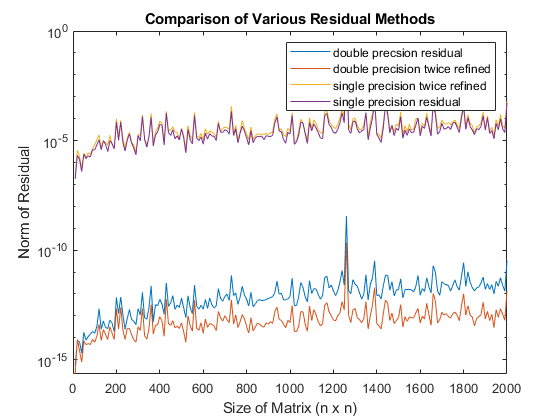

semilogy(nt,normb,nt,norm2step,nt,norm2stepSP,nt,normbsp)
title('Comparison of Various Residual Methods')
xlabel('Size of Matrix (n x n)')
ylabel('Norm of Residual')
legend('double precsion residual','double precision twice refined','single precision twice refined','single precision residual')



% 3. This is practical example of a small but real-life-type
% ill-conditioned problem The flow of water through two very different materials 
% gives this tridiagonal system of linear equations in which all the entries apart 
% from the three diagonals shown are zero The coefficient a  can be very small 
% indeed giving an ill-conditioned matrix.  Use ∆𝑥=1  𝑎=21,41,81,161.   
% Let the equation in which a first appears be about halfway down, say, equations 11, 
% 21, 41 and 81.For values of a =  1.0e-1,1.0e-3,  1.0e-5, 1.0e-7 and 1.0e-9, 
% 1.0e-11, 1.0e-13, 1.0e-15 compute the estimated condition number using the 
% matlab condition number estimator.Show that the condition number of the matrix 
% varies  with the value of a  according to   condition number  = 1/( const* a) 
% where roughly 0.1 < const < 1.   If 𝐻_1=8 and 𝐻_𝑟=4 Extend your program to 
% solve the system of equations for the cases above and show that one iterative 
% refinement reduces the norm of the residual but a second refinement does not 
% reduce it any more. Present your results as a table. 

a = [1e-1, 1e-3, 1e-5,1e-7,1e-9,1e-11,1e-13,1e-15];
mcond = zeros(4,8);
norms = zeros(4,8);
norms1 = zeros(4,8);
norms2 = zeros(4,8);

for k = 1:8
    for i = 1:4
        n = 20*i+1; 
        n_appears = n/2+.5; %11, 21, 41, 81
        A = zeros(n,n);
        A_1 = zeros(n-1,1);
        A_2 = zeros(n-1,1);
        A_3 = zeros(n,1);
        %first diagonal
        for j = 1:n-1
            if (j <= n_appears)
                A_1(j)=1;
            else
                A_1(j) = a(k); %todo update
            end
        end    
        %second diagonal
        for j = 1:n-1
            if (j < n_appears)
                A_2(j) = 1;
            else
                A_2(j) = a(k); %todo update
            end
        end
        %main diagonal
        for j = 1:n
            if (j<n_appears)
                A_3(j) = -2;
            elseif (j == n_appears)
                A_3(j) = -(1+a(k)); %todo update
            else
                A_3(j) = -2*a(k); %todo update
            end
        end    
        %add together
        A = A + diag(A_1,-1) + diag(A_2,1) +diag(A_3,0);
        mcond(i,k) = cond(A); %estimate condition number
        %matrix solving H1 = 8 H_r = 4
        %A*h = H solve for h
        H = zeros(n,1);
        H(1,1) = -8;
        H(n,1) = -a(k)*4;
        
        h = A\H; %solution
        r = A*h-H; %residual
        norms(i,k) = norm(r,inf);
        
        %residual refinement
        y = A\-r;
        h = h+y;
        r2 = A*h-H;
        norms1(i,k) = norm(r2,inf);
        
        %second refinement
        y = A\-r2;
        h = h+y;
        r3 = A*h-H;   
        norms2(i,k) = norm(r3,inf);
        
    end
end

%table values for results
mcond

mcond = 	1.0e+17 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0041    0.4141
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0162    1.6244
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0365    3.6492
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0649    6.4854


norms

norms = 	1.0e+-14 *

    0.0888    0.1332    0.1776    0.0888    0.1332    0.1332    0.0888    0.2665
    0.0888    0.1332    0.1776    0.1332    0.1776    0.0888    0.1776    0.2665
    0.1776    0.1776    0.1332    0.0888    0.1776    0.1776    0.1776    0.0888
    0.1776    0.1776    0.1776    0.1776    0.1776    0.0888    0.2665    0.1776


norms1

norms1 = 	1.0e+-14 *

    0.0444    0.0888    0.1332    0.0888    0.0444    0.0444    0.0888    0.1776
    0.0888    0.0888    0.0444    0.0888    0.0888    0.0888    0.0888    0.0888
    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888    0.1776    0.0888
    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888


norms2

norms2 = 	1.0e+-14 *

    0.0666    0.0888    0.1332    0.0888    0.0444    0.0444    0.0888    0.0888
    0.1776    0.0888    0.0444    0.0888    0.0888    0.1776    0.0888    0.0888
    0.0888    0.1776    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888
    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888    0.0888    0.1776
